## Contrast Adjustment Functions

There are few techniques to adjust contrast as used below :

- imadjust 

- histeq (Stretching the histogram out to use all the available intensitites roughly equally)

- adapthisteq ( Divides the tire image into tiles and increases intensity in the really dark overall tiles while keeping it the same in the well lit tiles )

- imhistmatch ( in this, another sharper ideal image is used to superimpose the histogram of the subject image, in order to better its contrast)

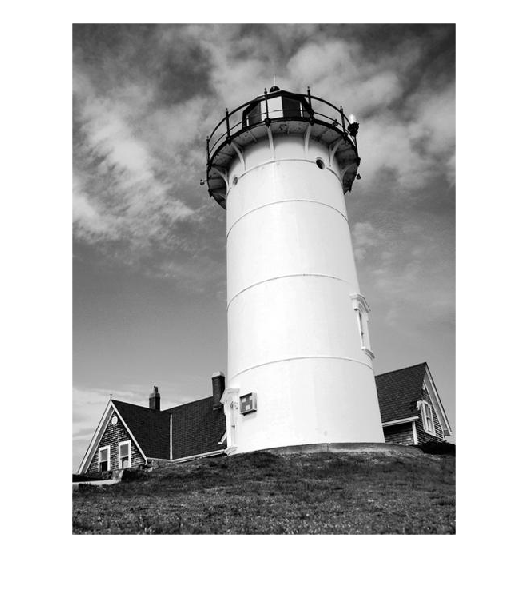

img = imread("lighthouseSmall.jpg");
imshow(img)

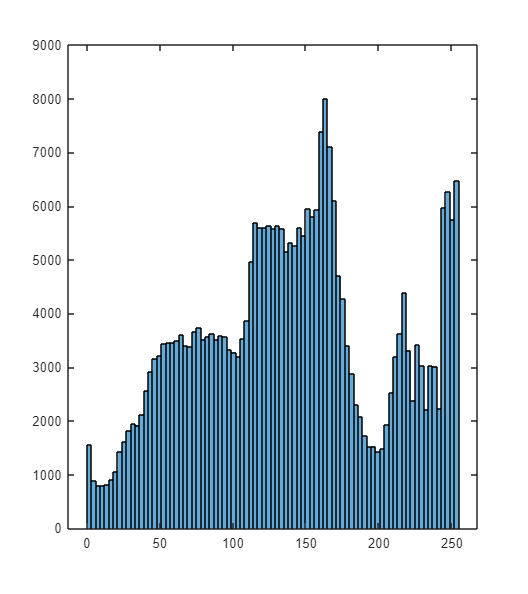

histogram(img)

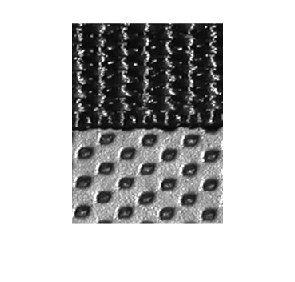

img = imread("bag.png");
imshow(img)

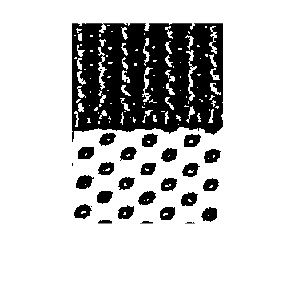

imshow(imbinarize(img,0.3842))

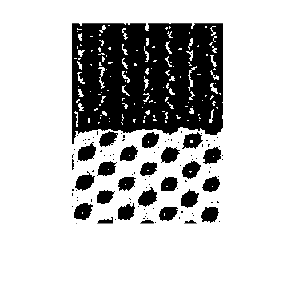

imshow(imbinarize(img,0.5))

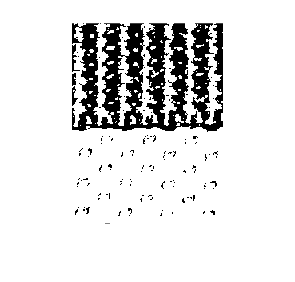

imshow(imbinarize(img,0.1255))

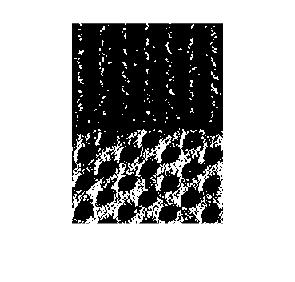

imshow(imbinarize(img,0.6471))

# Improving Image Contrast ( Video ) 

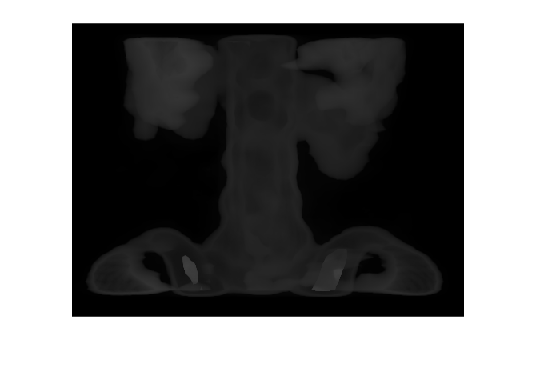

img = imread("spine.tif");
imshow(img)

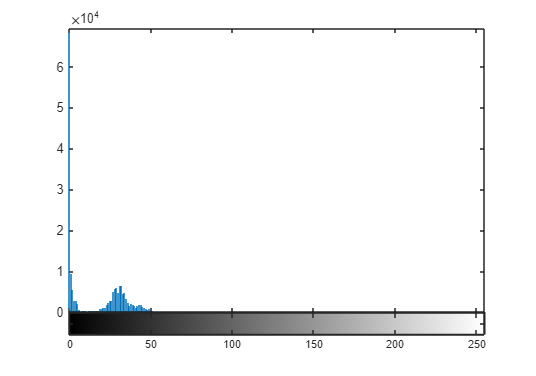

imhist(img)
ylim([0 Inf])

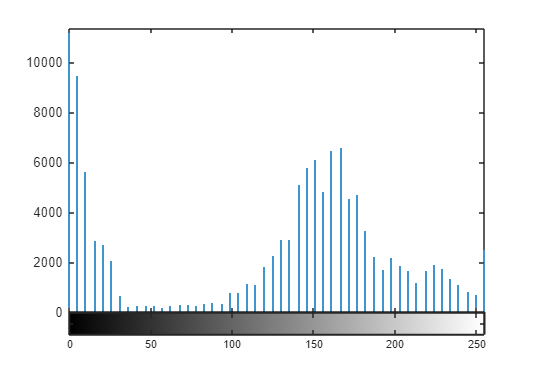

imgAdj = imadjust(img);
imhist(imgAdj);

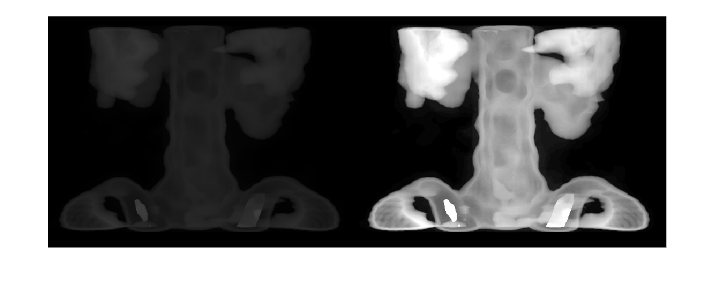

montage({img,imgAdj})

Adjusting the histogram to take in the values between the 10th and the 15% range, and specifying how far to stretch this part of the histogram. Here we take the entire range.

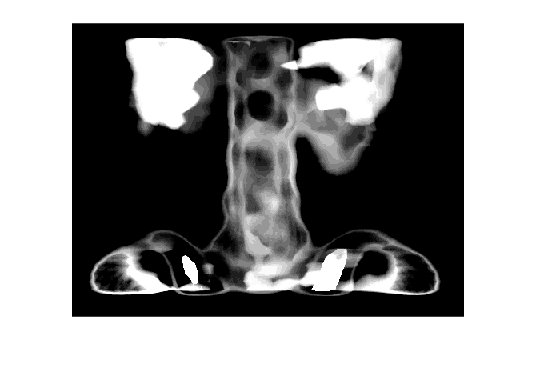

imgAdj2 = imadjust(img,[0.1,0.15],[0,1]);
imshow(imgAdj2)

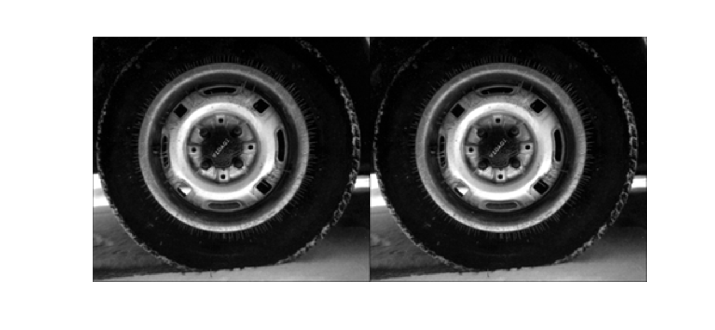

img = imread("tire.tif");
imgAdj = imadjust(img);
montage({img,imgAdj});

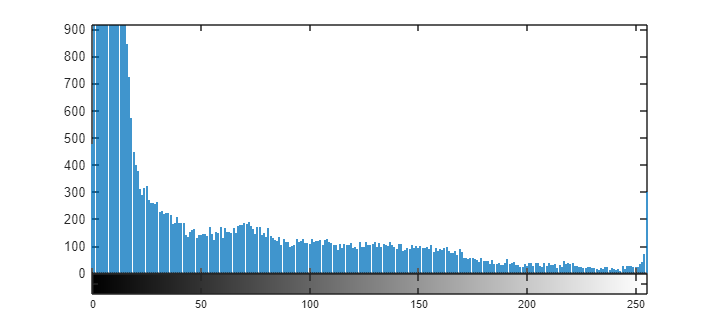

imhist(img)

Stretching the histogram out to use all the available intensitites roughly equally

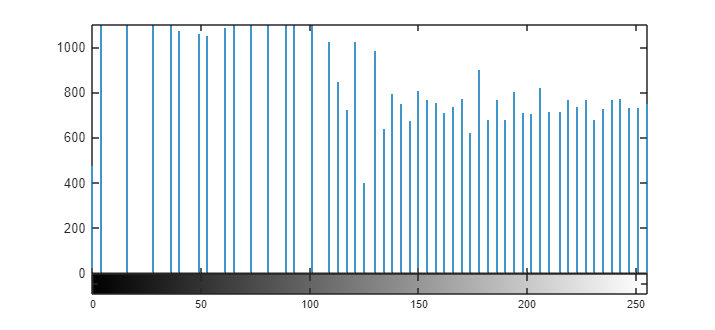

imgEq = histeq(img);
imhist(imgEq)

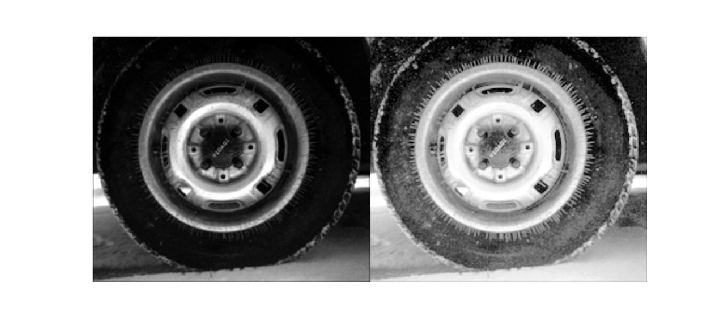

montage({img,imgEq})

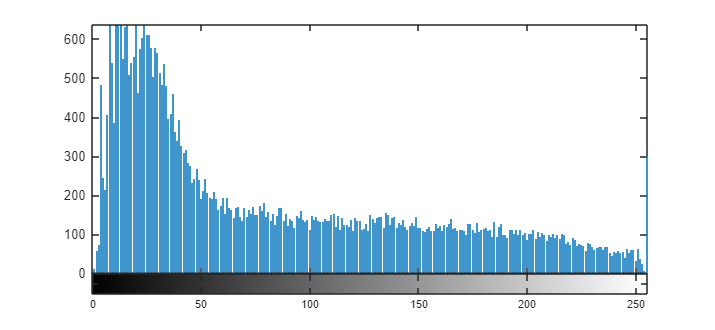

imgAdEq = adapthisteq(img);
imhist(imgAdEq)

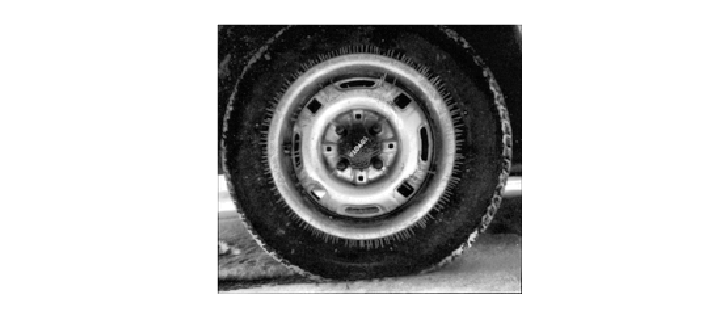

imshow(imgAdEq)

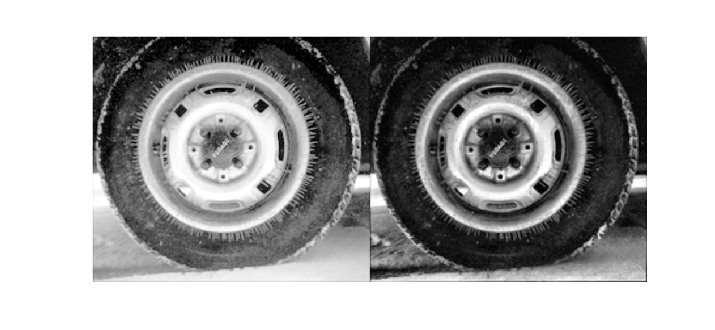

montage({imgEq,imgAdEq})

**Image from Crack Dataset**

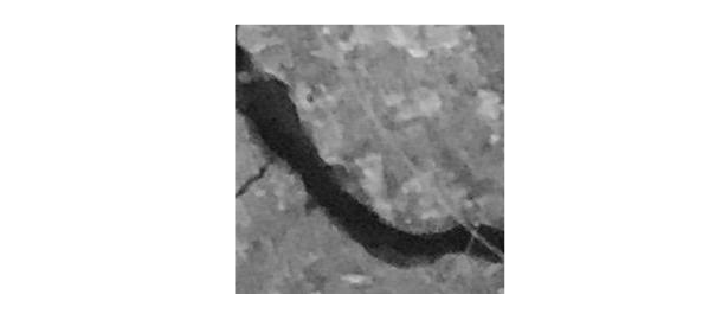

imRef = im2gray(imread("00155.jpg"));
imshow(imRef)

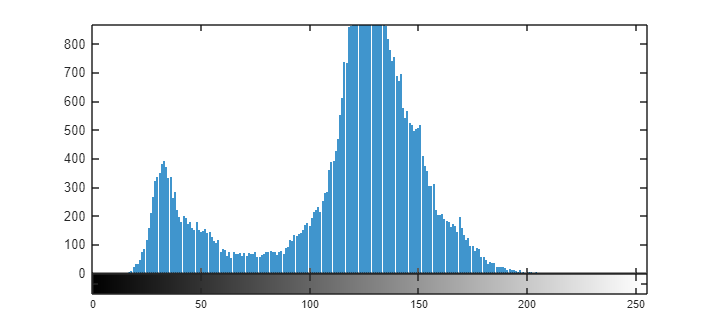

imhist(imRef)

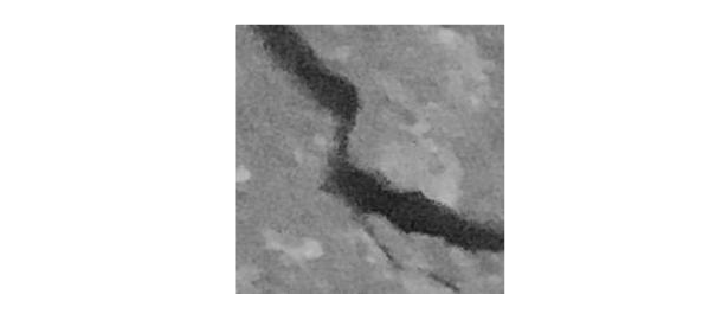

imRef2 = im2gray(imread("00175.jpg"));
imshow(imRef2)

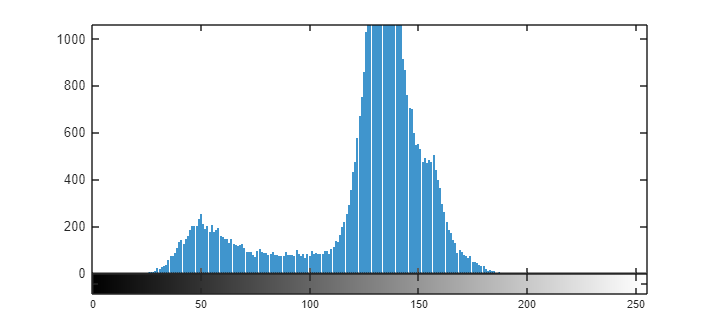

imhist(imRef2)

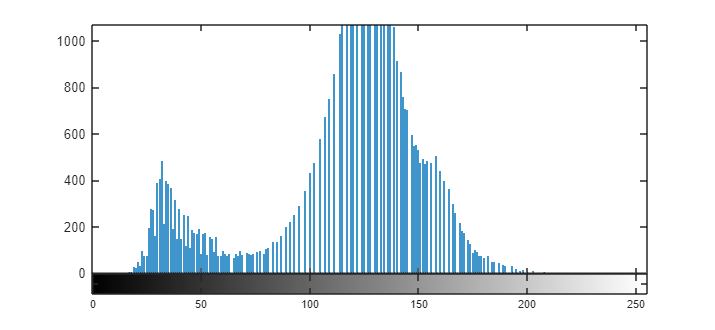

imgMatch = imhistmatch(imRef2,imRef,256);
imhist(imgMatch)

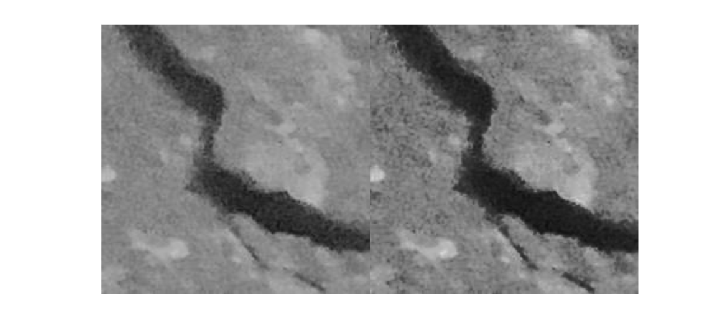

montage({imRef2,imgMatch})

**Project**

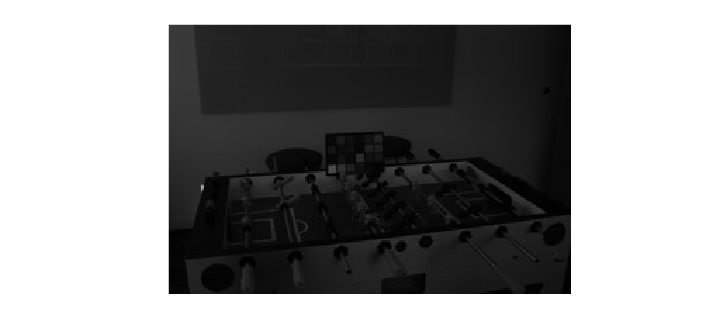

img = im2gray(imread("foosball.jpg"));
imshow(img)

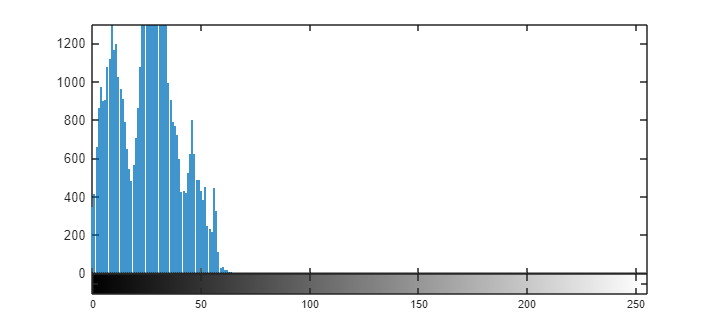

imhist(img)

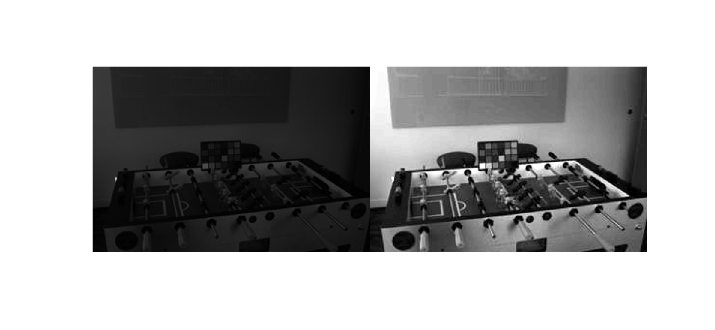

imad = imadjust(img);
montage({img,imad})

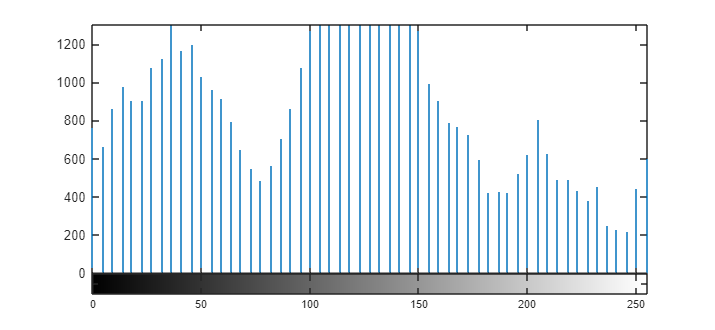

imhist(imad)

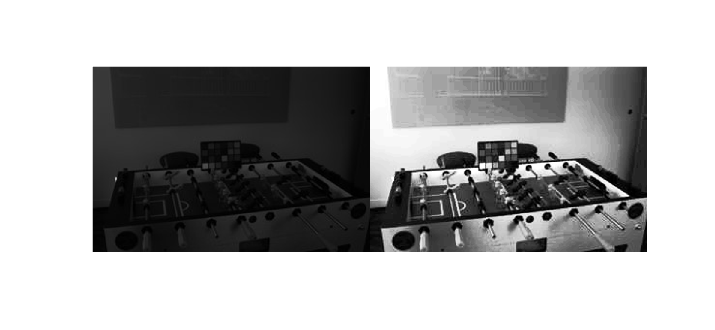


imgEq = histeq(img);
montage({img,imgEq})

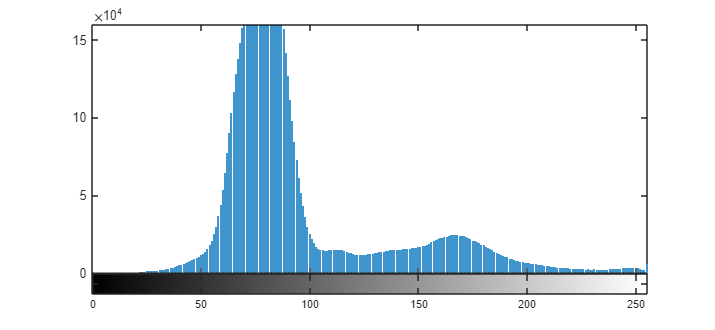

coins = im2gray(imread("coins1.jpg"));
imhist(coins)

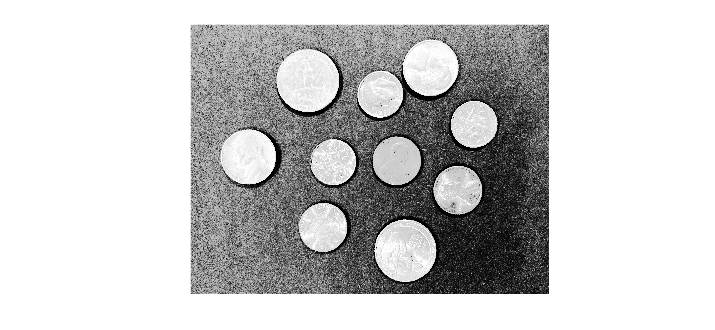

histeq(coins);

imhist(coins)

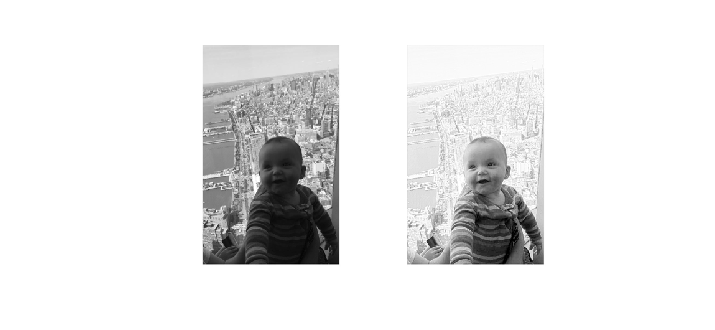

child = im2gray(imread("child.jpg"));
adjustedChild = imlocalbrighten(child);

montage({child,adjustedChild})

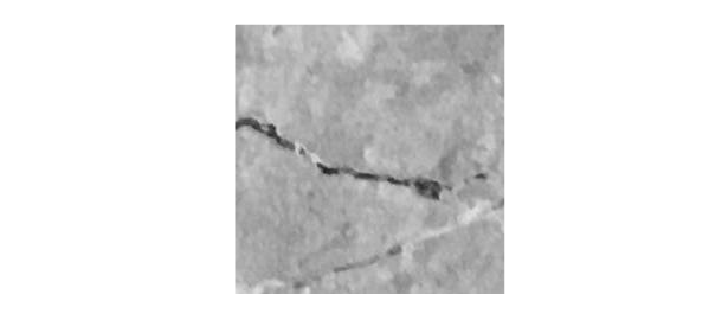

crack = im2gray(imread("00035.jpg"));
imshow(crack)

BW = imbinarize(crack)

BW = 227×227 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1 

BW = ~BW

BW = 227×227 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

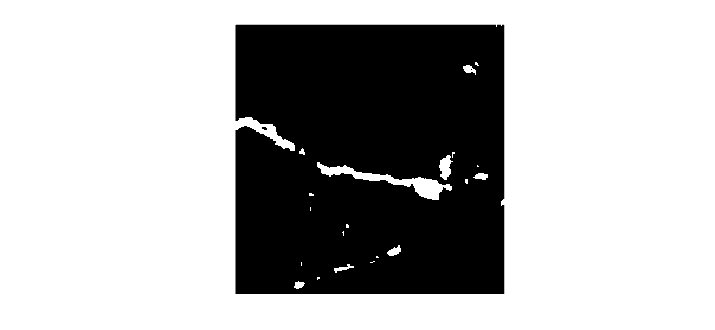

imshow(BW)

nnz(BW)

ans = 1800

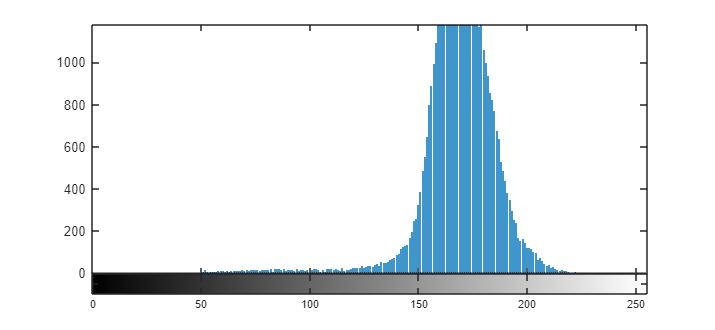

imhist(crack)

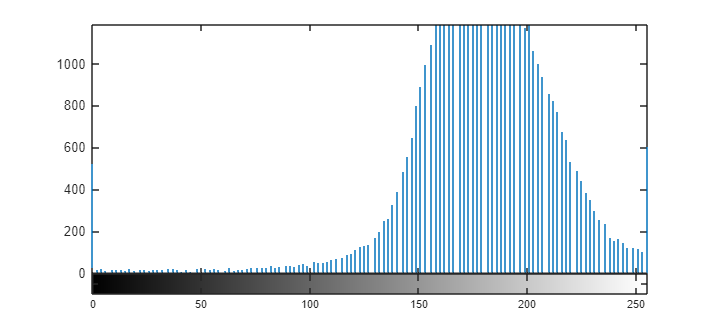

adjCrack1 = imadjust(crack);
imhist(adjCrack1)

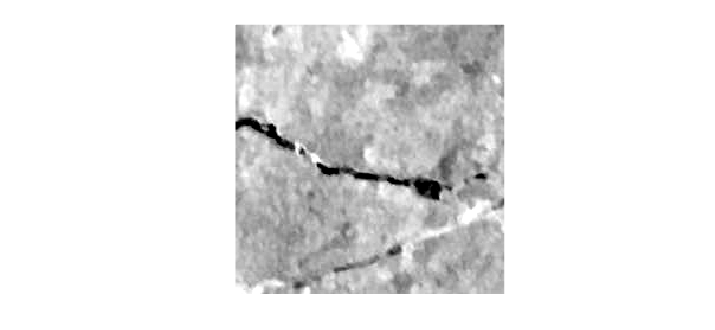


imshow(adjCrack1)


BWa = imbinarize(adjCrack1)

BWa = 227×227 logical array
   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1
   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1
   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1
   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   1   1   1   1

BWa = ~BWa

BWa = 227×227 logical array
   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   0   0   0   0

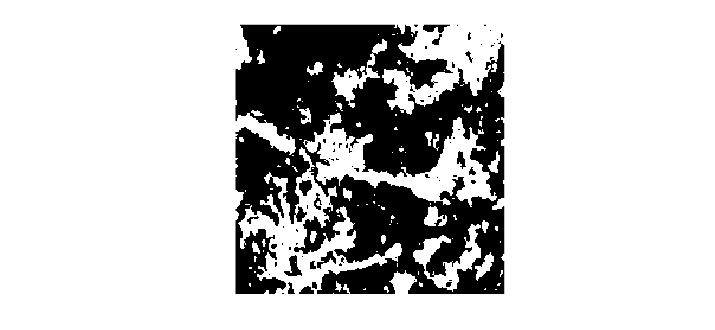

imshow(BWa)

nnz(BWa)

ans = 17751


adjCrack2 = histeq(crack);
BWaa = imbinarize(adjCrack2)

BWaa = 227×227 logical array
   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   1   1   1   1   1   1   1   1   1   1   1   1
   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1
   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1
   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1
   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   1   1   

BWaa = ~BWaa

BWaa = 227×227 logical array
   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0
   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0
   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   0   0   

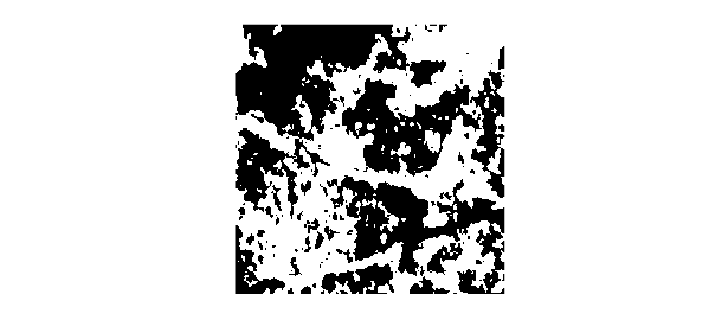

imshow(BWaa)

nnz(BWaa)

ans = 25780


adjCrack3 = adapthisteq(crack);
BWaaa = imbinarize(adjCrack3)

BWaaa = 227×227 logical array
   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1
   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1
   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1
   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1
   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0  

BWaaa = ~BWaaa

BWaaa = 227×227 logical array
   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0
   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0
   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0
   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0
   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1  

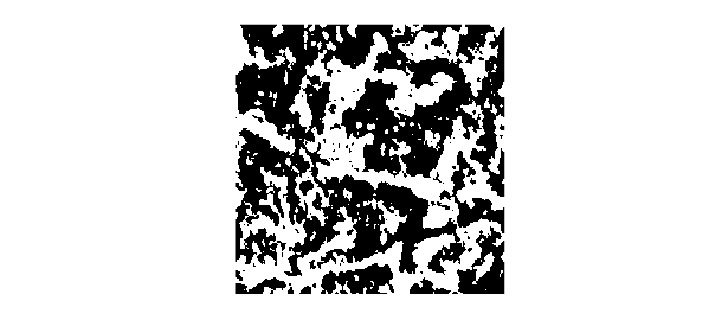

imshow(BWaaa)

nnz(BWaaa)

ans = 22638

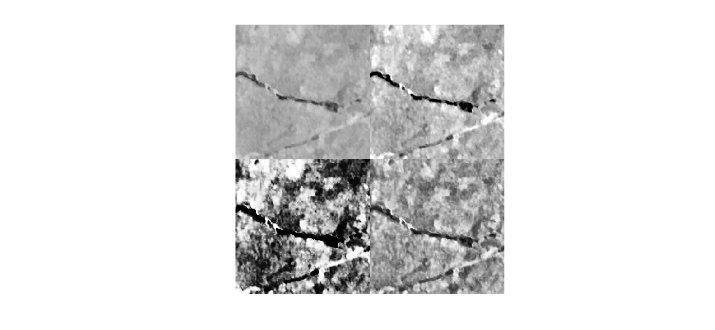


montage({crack,adjCrack1,adjCrack2,adjCrack3})

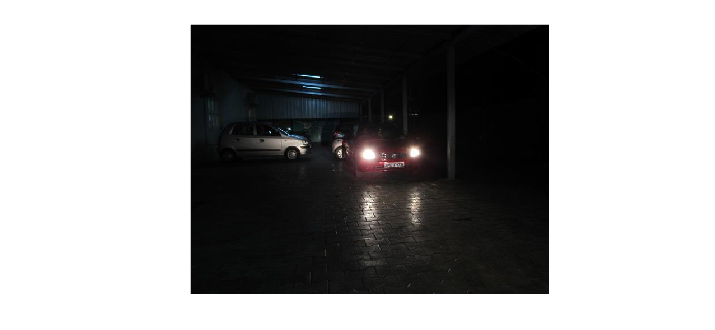

car = imread("car_3.jpg");
gscar = im2gray(car);
bcar = imlocalbrighten(car);
bgscar = imlocalbrighten(gscar);
imshow(car)

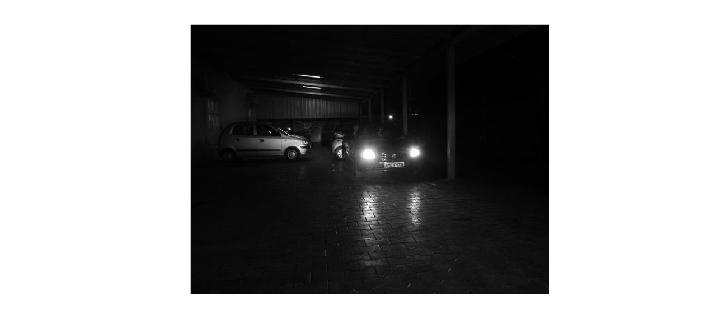

imshow(gscar)

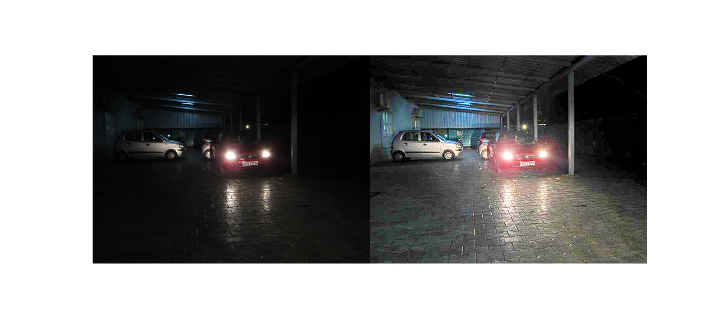

montage({car,bcar})

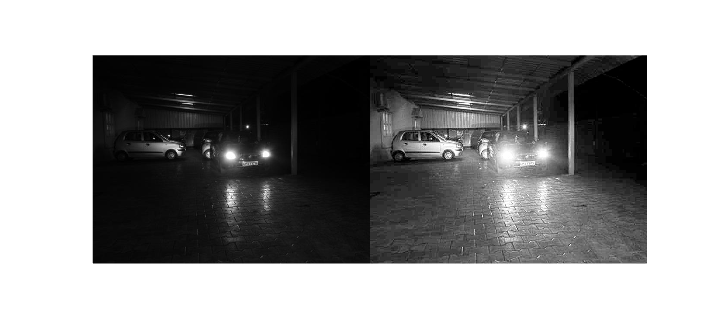

montage({gscar,bgscar})

x = mean2(gscar)

x = 18.7302

y = mean2(bgscar)

y = 77.1690

y-x 

ans = 58.4387

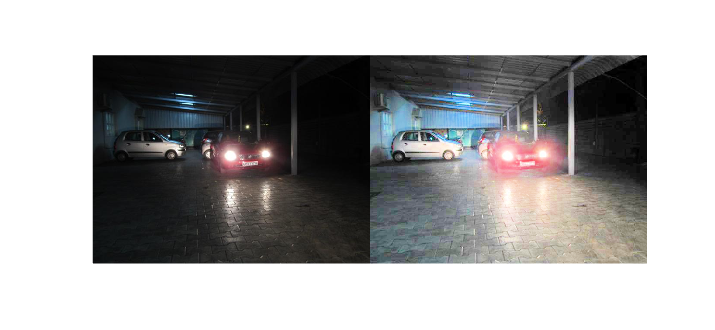

car2 = imread("car_2.jpg");
hsvcar2 = rgb2hsv(car2);
hsvcar2(:,:,3) = histeq(hsvcar2(:,:,3));
histEqgscar2 = hsv2rgb(hsvcar2);
histEqgscar2 = uint8(255 * mat2gray(histEqgscar2));
montage({car2,histEqgscar2})

x = mean2(car2)

x = 34.8282

y = mean2(histEqgscar2)

y = 117.2956

y-x

ans = 82.4673

mountain2 = imread("mountain2.jpg");
adjmountain2 = imreducehaze(mountain2);
x = mean2(mountain2)

x = 156.6022

y = mean2(adjmountain2)

y = 109.8292

x-y

ans = 46.7730

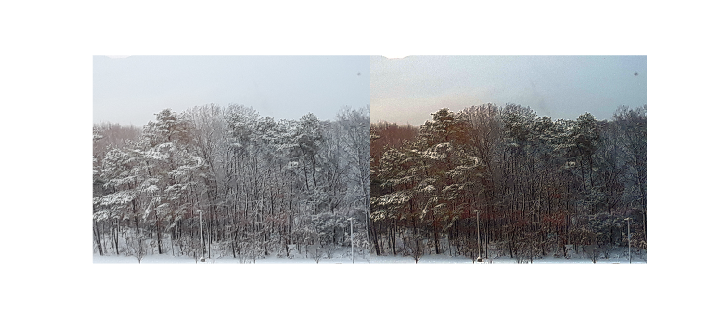

montage({mountain2,adjmountain2})

picks = imread("picks.jpg");
hsvpicks = rgb2hsv(picks)

hsvpicks = hsvpicks(:,:,1) =

         0         0    0.1667    0.1667    0.1667    0.1667    0.2000    0.2000    0.3333    0.2000    0.2000    0.2000    0.1667    0.1667    0.1667    0.1667         0    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667         0    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667         0    0.1667    0.1667    0.1667    0.1667    0.2000    0.2000    0.2000    0.2000    0.2083    0.2083    0.2000    0.2000    0.1667    0.1667    0.1667         0         0         0         0    0.1667    0.2083    0.2000    0.2222    0.2222    0.2000    0.2000    0.2000    0.2083    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.1667         0    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667    0.1667         0

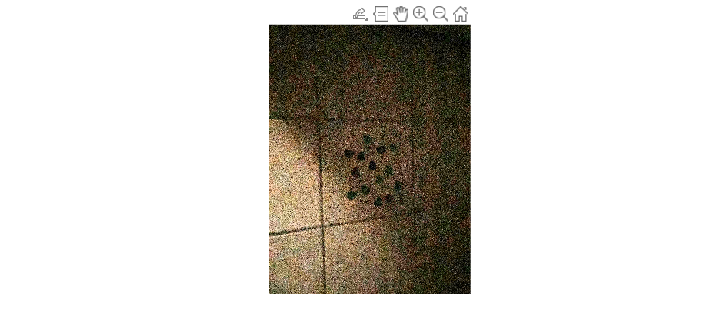

hsvpicks(:,:,3)=imadjust(hsvpicks(:,:,3));
rgbpicks = hsv2rgb(hsvpicks);
imshow(rgbpicks)

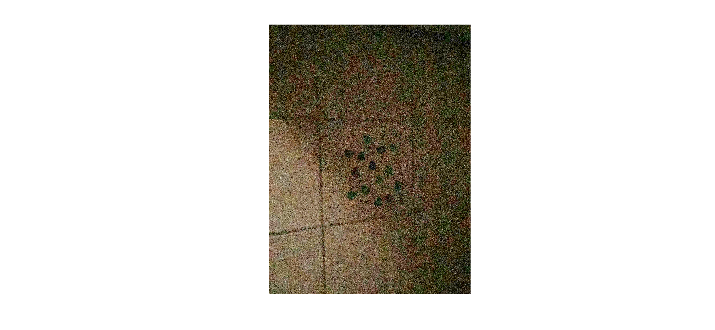

imshow(imlocalbrighten(picks))